% -------------------------------------------------------------------------
% Physics-aware machine learning
% Cyber-Physical Simulation, TU Darmstadt
% -------------------------------------------------------------------------
% Time integration of ODEs
% -------------------------------------------------------------------------

Select and run problem

probl = false

probl = logical
   0


Problem setup ...

if (probl)

... for Lotka-Volterra:

% Parameters
a = 1;
b = 0.5;
c = 2;
d = 1;
param = [a, b, c, d];
% ODE function
dydt = @(t,y) lotka(t, y, param);
% Initial condition
y0 = [2 1];
% Time step vector
t = 0:0.01:30;
else

... for harmonic oscillator:

% Parameters
m = 1;
k = 1;
c = 0.02;
f = @(t) .2*sin(2*pi*t-pi/2);
param = [m, k, c];
% ODE function
dydt = @(t,y) oscill(t, y, param, f);
% Initial condition
y0 = [1 0];
% Time step vector
t = 0:0.1:(3*2*pi); 
end

Time integration

dt = t(2)-t(1); % time step size
options = optimset('disp','off');


... with forward Euler:

tstart = tic;
yfe = y0';
for i = 1:length(t)-1
    yfe(:,i+1) = yfe(:,i) + dydt(t(i),yfe(:,i))*dt; 
end
tend = toc(tstart);
fprintf('Forward Euler: %7.5f sec \n',tend)

Forward Euler: 0.00697 sec 


.. with backward Euler:

tstart = tic;
ybf = yfe;
ybe = yfe;
for i = 1:length(t)-1
    ybf(:,i+1) = ybe(:,i) + dydt(t(i),ybe(:,i))*dt;     % forward initial guess for implicit
    fun = @(yn) ybf(:,i) + dt*dydt(t(i+1),yn)-yn;       % set up function x-f(x)= g(x) = 0
    [ybe(:,i+1),fval,exitflag] = fsolve(fun,ybf(:,i+1),options);    % use fsolve to find next point
    if (exitflag ~= 1 || norm(fval) > 1e-5)
        problem = 1;
    end
end
tend = toc(tstart);
fprintf('Backward Euler: %7.5f sec \n',tend)

Backward Euler: 0.11153 sec 


... with Runge-Kutta method (ODE45):

tstart = tic;
[trk, yrk] = ode45(dydt,[t(1) t(end)],y0);
trk = trk';
yrk = yrk';
tend = toc(tstart);
fprintf('ODE45 RK method: %7.5f sec \n',tend)

ODE45 RK method: 0.00595 sec 


Plot results

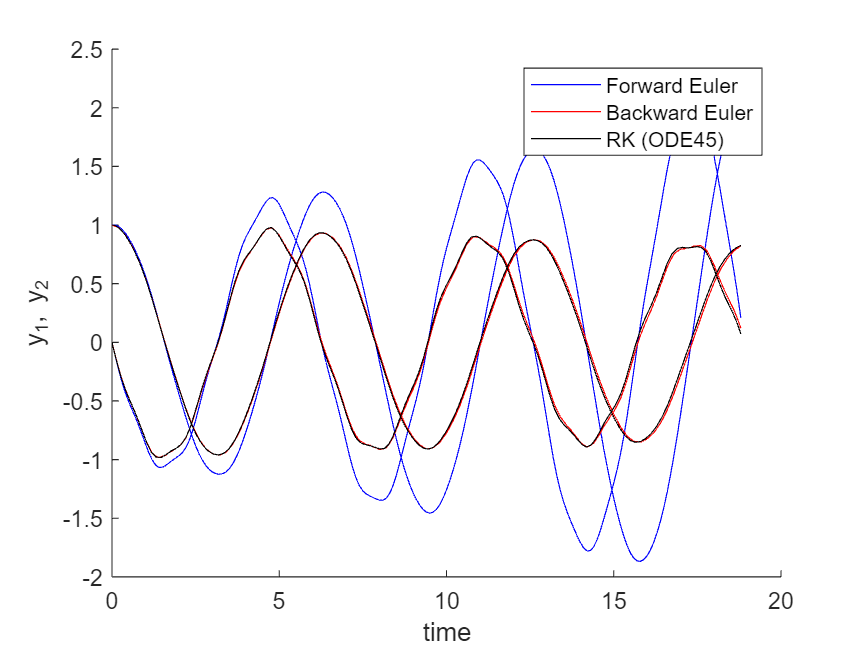

figure; 
hold on
plot(t,yfe,'blue')
plot(t,ybe,'red')
plot(trk,yrk,'black')
xlabel('time')
ylabel('y_1, y_2')
l0 = plot(nan, nan, 'blue');
l1 = plot(nan, nan, 'red');
l2 = plot(nan, nan, 'black');
legend([l0 l1, l2], 'Forward Euler', 'Backward Euler', 'RK (ODE45)')

Lotka-Volterra equation: 

 
$$\dot y_1 = a \,y_1 - b\, y_1 y_2 \\ 
\dot y_2 = c\, y_1 y_2 - d\, y_2$$


function [dy, Dy] = lotka(t, y, param)
    a = param(1);
    b = param(2);
    c = param(3);
    d = param(4);
    dy = [ a*y(1) - b*y(1)*y(2); 
           c*y(1)*y(2) - d*y(2) ]; 
    if (nargout > 1)
        Dy = [ a-b*y(2), b*y(1);
               c*y(2), c*y(1)-d ];
    end
end

Damped harmonic oscillator: 

 
$$\dot y_1 = y_2 \\ 
\dot y_2 = -\frac{k}{m} y_1 - \frac{c}{m}y_2 + \frac{1}{m} f(t)$$


function [dy, Dy] = oscill(t, y, param, f)
    m = param(1);
    k = param(2);
    c = param(3);
    dy = [ y(2); 
           -k/m*y(1) - c/m*y(2) + f(t)/m ]; 
    if (nargout > 1)
        Dy = [ 0, 1;
               -k/m, - c/m ];
    end
end